% save the data after sunning the main code for cylinder
close all;
mkdir lib_bent_cyl

% save('.\lib_bent_cyl\result.mat')

% clear all and load just to make sure all the unwanted variables are
% removed
clear all;
load('.\lib_bent_cyl\result.mat')

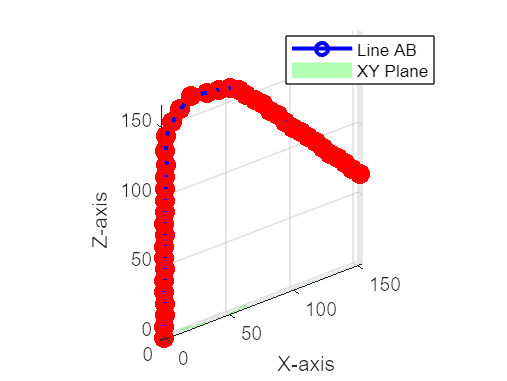

%% Set paths for dependencies, library and interpreters
set_interpreter_paths
% save('.\lib_bent_cyl\data_lib.mat')
global geodesic_library;
geodesic_library = 'geodesic_release';

% Calculate the vector AB to get the angle wrt xy plane
% the reference plane depends on the type and orientation of the
% 3D object

for i = 1:length(skel) - 1
    % Define the coordinates of points A and B on the skeleton/ reeb graph
    x1 = skel(i, 1); y1 = skel(i, 2); z1 = skel(i, 3);
    x2 = skel(i + 1, 1); y2 = skel(i + 1, 2); z2 = skel(i + 1, 3);

    % Calculate the vector AB to get the angle wrt xy plane
    % the reference plane depends on the type and orientation of the
    % 3D object
    AB = [x2 - x1, y2 - y1, z2 - z1];

    % Plot the line joining points A and B
    plot3([x1, x2], [y1, y2], [z1, z2], 'b-o', 'LineWidth', 2);
    hold on;

    % Plot the XY plane (the reference plane)
    [xMesh, yMesh] = meshgrid(linspace(min([x1, x2]), max([x1, x2]), 10), linspace(min([y1, y2]), max([y1, y2]), 10));
    zMesh = zeros(size(xMesh));
    surf(xMesh, yMesh, zMesh, 'FaceAlpha', 0.3, 'FaceColor', 'g', 'EdgeColor', 'none');

    % Set axis labels and plot properties
    xlabel('X-axis');
    ylabel('Y-axis');
    zlabel('Z-axis');
    grid on;
    axis equal;

    % Calculate the angle in radians using the line joining two points on
    % the skeleton/reeb
    cosTheta = dot(AB, [0, 0, 1]) / norm(AB);
    thetaRadians = acos(cosTheta);

    % Convert the angle to degrees
    thetaDegrees(i) = rad2deg(thetaRadians);

    % Display the angle as text (to be used in segmentation to calculate
    % critical points
    % angleText = sprintf('A: %.2f deg', thetaDegrees);
    % text(x1, y1, z1, angleText, 'FontSize', 12, 'Color', 'r');

    % Display points A and B
    scatter3([x1, x2], [y1, y2], [z1, z2], 100, 'r', 'filled');

    % Display legend
    legend('Line AB', 'XY Plane', 'Location', 'Best');
    hold on;
end

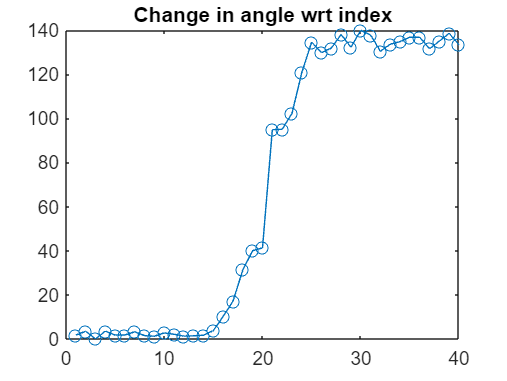


% Calculate derivatives of the angles to find the segments 
% the saddle points and inflection points (points where the graph of a function changes
% concavity) help in identifying the critical points and to reassure the
% points obtainted from thresholding method
x = 1:length(thetaDegrees);
y = thetaDegrees;
dx = x(2) - x(1);
dy_dx_approx = diff(y) / dx;

% Plotting for visualization
figure;
plot(x, y, '-o');
title('Change in angle wrt index');


% Apply a moving average for smoothing
window_size = 5;
y_smoothed = movmean(y, window_size);

% Calculate the second derivative using the diff function
dy = diff(y_smoothed, 2) ./ diff(x, 2);

% Find the indices where the second derivative changes sign
inflection_indices = find(diff(sign(dy)) ~= 0) + 1;

% Extract inflection points
inflection_points_x = x(inflection_indices);
inflection_points_y = y_smoothed(inflection_indices);
stackpoints = inflection_points_y - circshift(inflection_points_y, 1);
A = stackpoints;
critical_threshold = 10;
stackpoints(stackpoints<critical_threshold) = [];
% Given subset after thresholding
SubsetValues = stackpoints;

% Find indices of subset values in the Ab vector
SubsetIndices = find(ismember(A, SubsetValues));

% Display the indices
disp('Indices of Subset Values in Ab:');

Indices of Subset Values in Ab:


disp(SubsetIndices);

     8    11    12    13    15



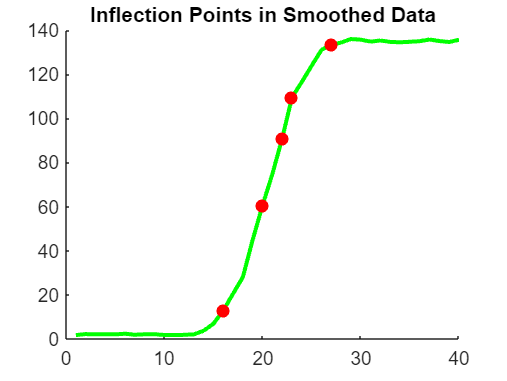

inflection_points_x = inflection_points_x(SubsetIndices);
inflection_points_y = inflection_points_y(SubsetIndices);
% Plot the original data, smoothed data, and mark inflection points
figure;
% plot(x, y, '-b', 'LineWidth', 2, 'DisplayName', 'Original Data');
hold on;
plot(x, y_smoothed, '-g', 'LineWidth', 2, 'DisplayName', 'Smoothed Data');
scatter(inflection_points_x, inflection_points_y, 'ro', 'MarkerFaceColor', 'r', 'DisplayName', 'Inflection Points');
title('Inflection Points in Smoothed Data');

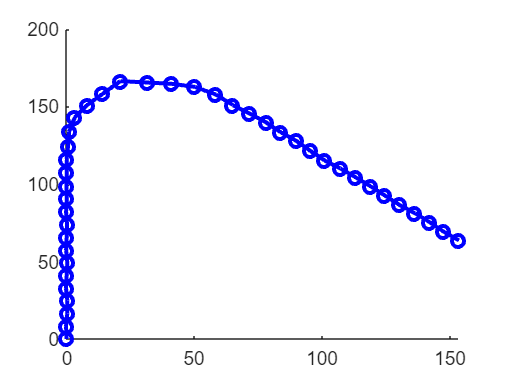


figure;
for i = 1:length(skel) - 1
    % Define the coordinates of points A and B on the skeleton/ reeb graph
    x1 = skel(i, 1); y1 = skel(i, 2); z1 = skel(i, 3);
    x2 = skel(i + 1, 1); y2 = skel(i + 1, 2); z2 = skel(i + 1, 3);
    % Calculate the vector AB to get the angle wrt xy plane
    % the reference plane depends on the type and orientation of the
    % 3D object
    AB = [x2 - x1, y2 - y1, z2 - z1];
    % Plot the line joining points A and B
    plot3([x1, x2], [y1, y2], [z1, z2], 'b-o', 'LineWidth', 2);
    hold on;
end
view([0 -0])



% x1 = skel(inflection_points_x, 1); y1 = skel(inflection_points_x, 2); z1 = skel(inflection_points_x, 3);
% plot3(x1,y1,z1, 'r-o', 'LineWidth', 2);
% hold on;
% x1 = mid(1:54, 1); y1 = mid(1:54, 2); z1 = mid(1:54, 3);
% plot3(x1,y1,z1, '*-r', 'LineWidth', 2);
% x1 = seam(1:54, 1); y1 = seam(1:54, 2); z1 = seam(1:54, 3);
% plot3(x1,y1,z1, '*-b', 'LineWidth', 2);
% x1 = mid(55:68, 1); y1 = mid(55:68, 2); z1 = mid(55:68, 3);
% plot3(x1,y1,z1, '*-b', 'LineWidth', 2);
% x1 = seam(55:68, 1); y1 = seam(55:68, 2); z1 = seam(55:68, 3);
% plot3(x1,y1,z1, '*-r', 'LineWidth', 2);
% x1 = mid(69:75, 1); y1 = mid(69:75, 2); z1 = mid(69:75, 3);
% plot3(x1,y1,z1, '*-r', 'LineWidth', 2);
% x1 = seam(69:75, 1); y1 = seam(69:75, 2); z1 = seam(69:75, 3);
% plot3(x1,y1,z1, '*-b', 'LineWidth', 2);
% x1 = mid(76:92, 1); y1 = mid(76:92, 2); z1 = mid(76:92, 3);
% plot3(x1,y1,z1, '*-b', 'LineWidth', 2);
% x1 = seam(76:92, 1); y1 = seam(76:92, 2); z1 = seam(76:92, 3);
% plot3(x1,y1,z1, '*-r', 'LineWidth', 2);
% x1 = mid(76:92, 1); y1 = mid(76:92, 2); z1 = mid(76:92, 3);
% plot3(x1,y1,z1, '*-b', 'LineWidth', 2);
% x1 = seam(76:92, 1); y1 = seam(76:92, 2); z1 = seam(76:92, 3);
% plot3(x1,y1,z1, '*-r', 'LineWidth', 2);
% x1 = mid(93:end, 1); y1 = mid(93:end, 2); z1 = mid(93:end, 3);
% plot3(x1,y1,z1, '*-r', 'LineWidth', 2);
% x1 = seam(93:end, 1); y1 = seam(93:end, 2); z1 = seam(93:end, 3);
% plot3(x1,y1,z1, '*-b', 'LineWidth', 2);


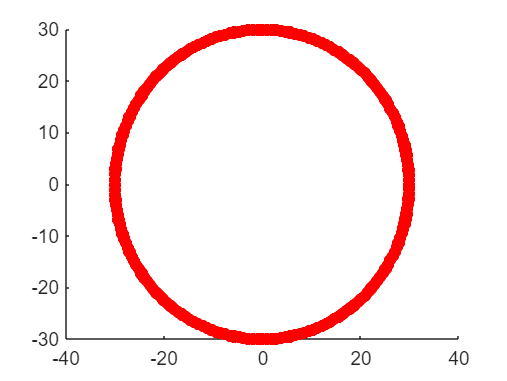

mesh has 5368 vertices, 10342 faces, 15709 edges
392 edges are boundary edges
shortest/longest edges are 0.303951/5.87726 = 0.0517165
enclosing XYZ box: X[-30,174.682] Y[-29.9886,29.9886] Z[0,198.934]
approximate diameter of the mesh is 291.662
min/max face angles are 5.25311/145.568 degrees



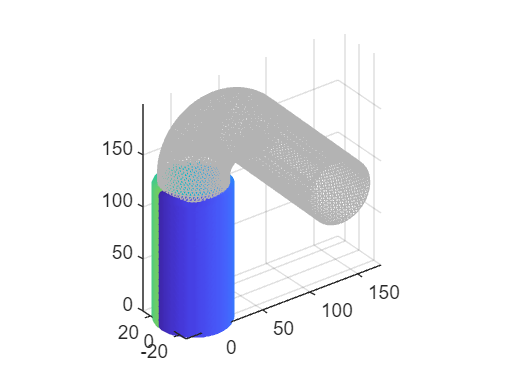

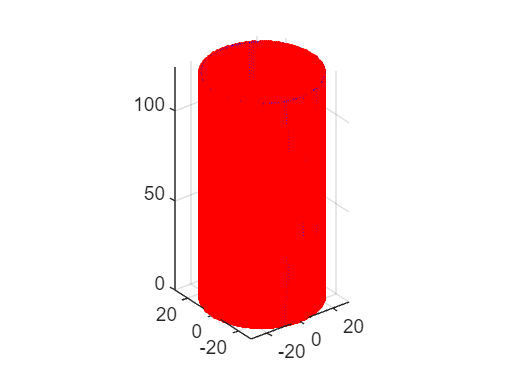

all_cont =            1         150         299         448         597         746         895        1044        1193        1342        1491        1640        1789        1938        2087        2236        2385        2534        2683        2832        2981        3130        3279        3428        3577        3726        3875        4024        4173        4322        4471        4620        4769        4918        5067        5216        5365        5514        5663        5812        5961        6110        6259        6408        6557        6706        6855        7004        7153        7302
           2         151         300         449         598         747         896        1045        1194        1343        1492        1641        1790        1939        2088        2237        2386        2535        2684        2833        2982        3131        3280        3429        3578        3727        3876        4025        4174        4323        4472        4621    

onedge = 29204×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


wvec =    -99   -98   -97   -96   -95   -94   -93   -92   -91   -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79   -78   -77   -76   -75   -74   -73   -72   -71   -70   -69   -68   -67   -66   -65   -64   -63   -62   -61   -60   -59   -58   -57   -56   -55   -54   -53   -52   -51   -50


idx_first =            1
         150
         299
         448
         597
         746
         895
        1044
        1193
        1342


idx_last =          149
         298
         447
         596
         745
         894
        1043
        1192
        1341
        1490


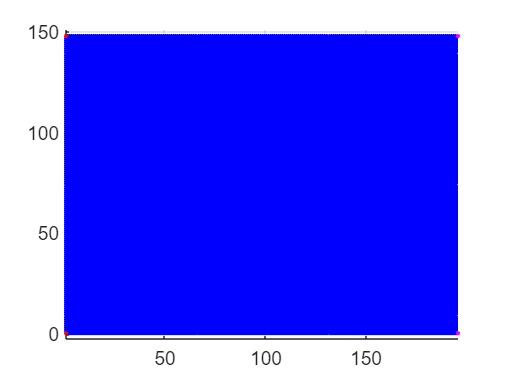

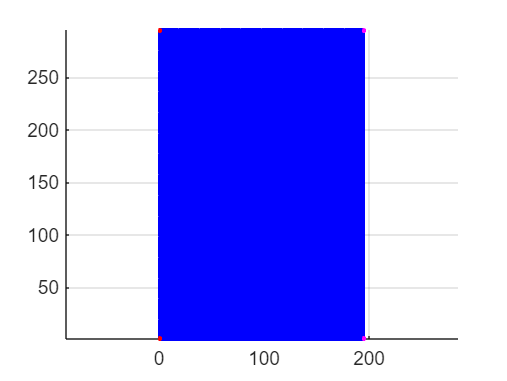

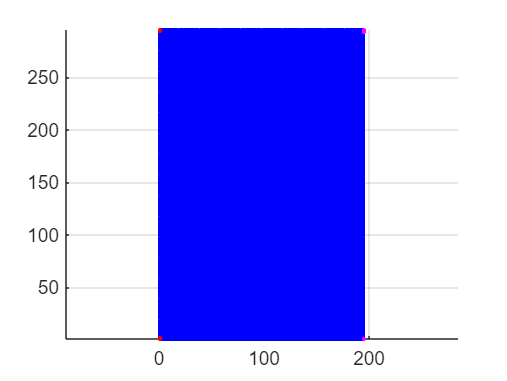

jac_final = 1×1 cell array
    {297×1 cell}


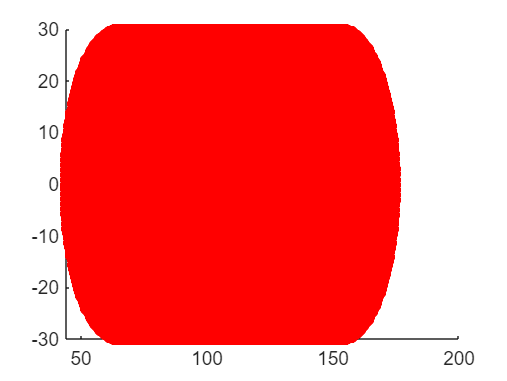

mesh has 5368 vertices, 10342 faces, 15709 edges
392 edges are boundary edges
shortest/longest edges are 0.303951/5.87726 = 0.0517165
enclosing XYZ box: X[-30,174.682] Y[-29.9886,29.9886] Z[0,198.934]
approximate diameter of the mesh is 291.662
min/max face angles are 5.25311/145.568 degrees



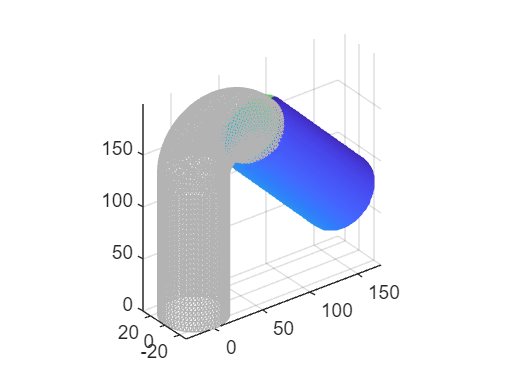

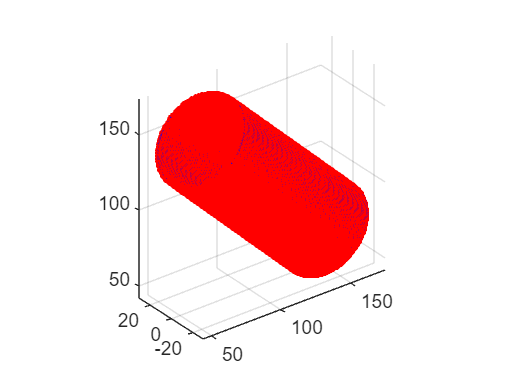

all_cont =            1         151         301         451         601         751         901        1051        1201        1351        1501        1651        1801        1951        2101        2251        2401        2551        2701        2851        3001        3151        3301        3451        3601        3751        3901        4051        4201        4351        4501        4651        4801        4951        5101        5251        5401        5551        5701        5851        6001        6151        6301        6451        6601        6751        6901        7051        7201        7351
           2         152         302         452         602         752         902        1052        1202        1352        1502        1652        1802        1952        2102        2252        2402        2552        2702        2852        3002        3152        3302        3452        3602        3752        3902        4052        4202        4352        4502        4652    

onedge = 29400×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


wvec =    -99   -98   -97   -96   -95   -94   -93   -92   -91   -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79   -78   -77   -76   -75   -74   -73   -72   -71   -70   -69   -68   -67   -66   -65   -64   -63   -62   -61   -60   -59   -58   -57   -56   -55   -54   -53   -52   -51   -50


idx_first =            1
         151
         301
         451
         601
         751
         901
        1051
        1201
        1351


idx_last =          150
         300
         450
         600
         750
         900
        1050
        1200
        1350
        1500


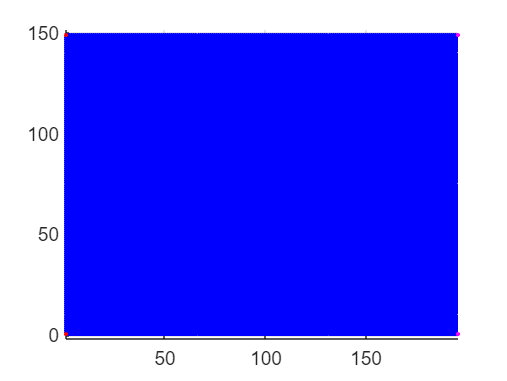

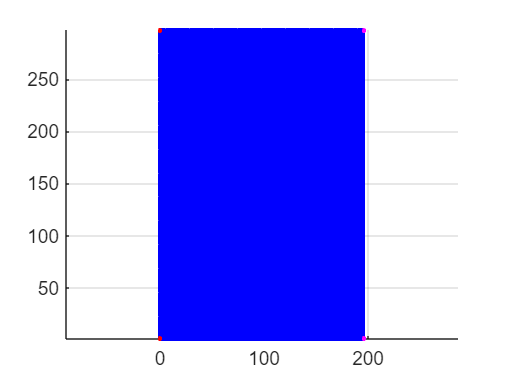

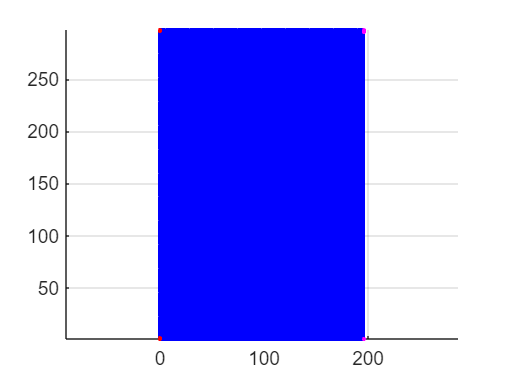

jac_final = 1×2 cell array
    {297×1 cell}    {299×1 cell}


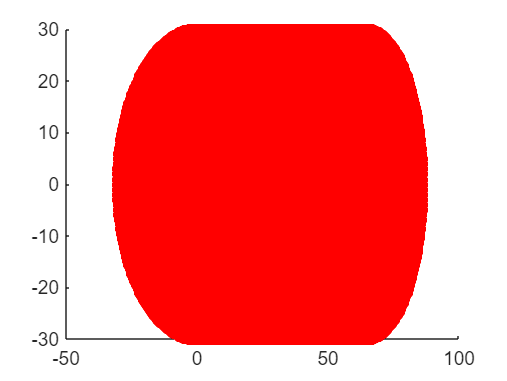

mesh has 5368 vertices, 10342 faces, 15709 edges
392 edges are boundary edges
shortest/longest edges are 0.303951/5.87726 = 0.0517165
enclosing XYZ box: X[-30,174.682] Y[-29.9886,29.9886] Z[0,198.934]
approximate diameter of the mesh is 291.662
min/max face angles are 5.25311/145.568 degrees



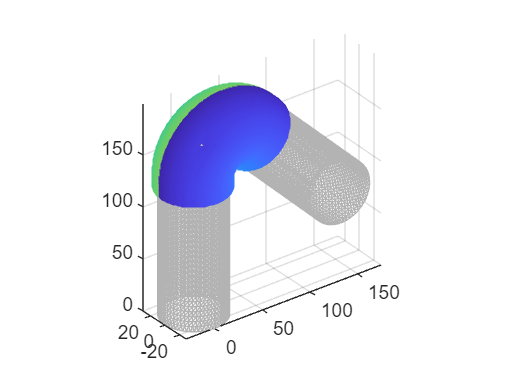

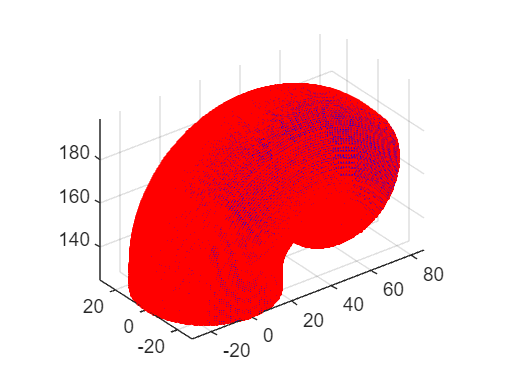

all_cont =            1         205         409         613         817        1020        1223        1426        1628        1830        2031        2231        2430        2629        2827        3023        3218        3412        3605        3796        3986        4175        4362        4547        4731        4913        5093        5271        5447        5621        5793        5963        6131        6296        6459        6620        6778        6934        7088        7239        7388        7534        7678        7819        7957        8093        8226        8356        8484        8609
           2         206         410         614         818        1021        1224        1427        1629        1831        2032        2232        2431        2630        2828        3024        3219        3413        3606        3797        3987        4176        4363        4548        4732        4914        5094        5272        5448        5622        5794        5964    

onedge = 23456×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


wvec =    -99   -98   -97   -96   -95   -94   -93   -92   -91   -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79   -78   -77   -76   -75   -74   -73   -72   -71   -70   -69   -68   -67   -66   -65   -64   -63   -62   -61   -60   -59   -58   -57   -56   -55   -54   -53   -52   -51   -50


idx_first =            1
         205
         409
         613
         817
        1020
        1223
        1426
        1628
        1830


idx_last =          204
         408
         612
         816
        1019
        1222
        1425
        1627
        1829
        2030


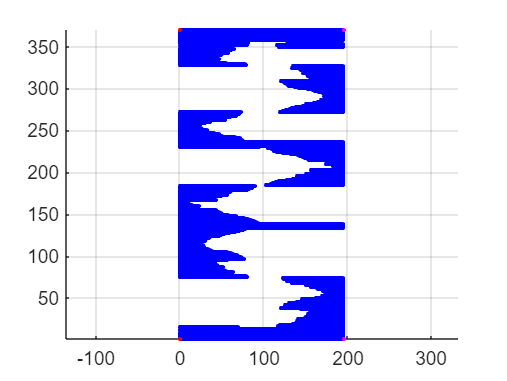

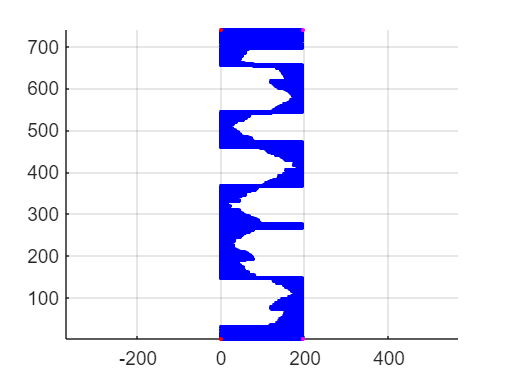

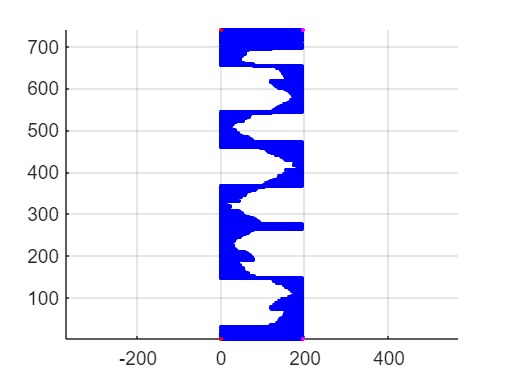

jac_final = 1×3 cell array
    {297×1 cell}    {299×1 cell}    {743×1 cell}


for k=1:3
% critical_point = 14;%for 10/5 h/w
critical_point = 149;
[all_cont,onedge,wvec,idx_first, idx_last] = segknittingmap(k,lt,all_res,ltime,TR_start,w,critical_point)
jac_final{k} = jac_maker(all_cont,onedge,wvec,idx_first, idx_last)
end

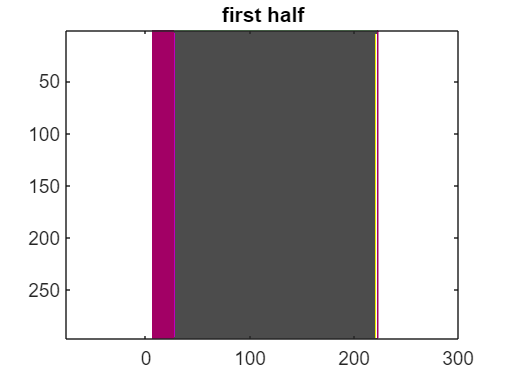

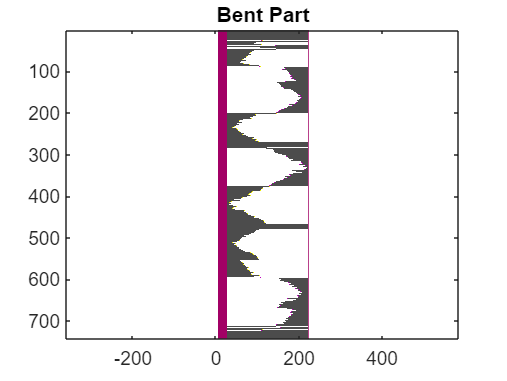

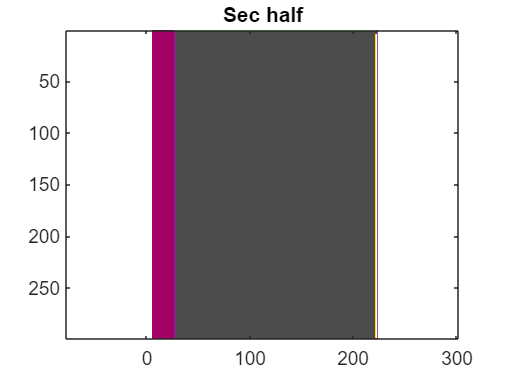

p = {jac_final{1}, jac_final{3}, jac_final{2}};
titles = ["first half", "Bent Part", "Sec half"];

for m = 1:3
    jac_ascii = p{1, m};
    jacim = ones(length(jac_ascii), length(jac_ascii{1}), 3);

    colorsmat = zeros(length(trueops), 3);
    for i = 1:length(trueops)
        colorsmat(i, :) = reshape(rgbs(i, :, :), 1, 3);
    end

    colorsmat = colorsmat ./ 255;

    for k = 1:length(jac_ascii)
        for k2 = 1:length(trueops)
            jacim(k, (jac_ascii{k} == trueops(k2)), 1) = colorsmat(k2, 1);
            jacim(k, (jac_ascii{k} == trueops(k2)), 2) = colorsmat(k2, 2);
            jacim(k, (jac_ascii{k} == trueops(k2)), 3) = colorsmat(k2, 3);
        end
    end

    figure;
    image(jacim)
    title(titles(m))
    axis equal
end

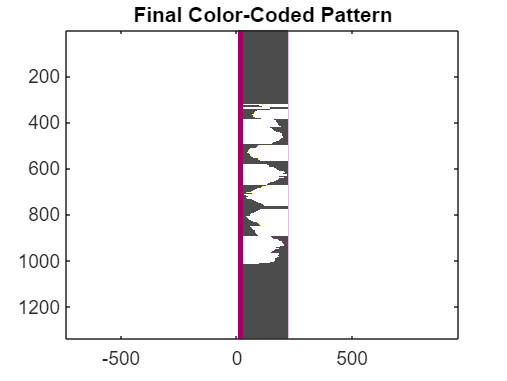


% Combine the jac files of the segments by iterating over the 
% number of segments obtained
jac_ascii = [jac_final{1}', jac_final{3}', jac_final{2}'];
jac_ascii = jac_ascii';
jacim = ones(length(jac_ascii), length(jac_ascii{1}), 3);

colorsmat = zeros(length(trueops), 3);
for i = 1:length(trueops)
    colorsmat(i, :) = reshape(rgbs(i, :, :), 1, 3);
end

colorsmat = colorsmat ./ 255;

for k = 1:length(jac_ascii)
    for k2 = 1:length(trueops)
        jacim(k, (jac_ascii{k} == trueops(k2)), 1) = colorsmat(k2, 1);
        jacim(k, (jac_ascii{k} == trueops(k2)), 2) = colorsmat(k2, 2);
        jacim(k, (jac_ascii{k} == trueops(k2)), 3) = colorsmat(k2, 3);
    end
end

% Plot the final color-coded pattern
figure;
image(jacim)
title('Final Color-Coded Pattern')
axis equal


%% Save the file in the jacfile format
jacpic = strcat([filename(1:end-4), '_', date, '_', KNIT_STR{KNIT}, '.bmp']);
jacjac = strcat([filename(1:end-4), '_', date, '_', KNIT_STR{KNIT}, '.jac']);
fnpic = fullfile(pwd, strcat(['..', filesep, 'Results']), jacpic);
fnjac = fullfile(pwd, strcat(['..', filesep, 'Results']), jacjac);
imwrite(jacim, fnpic)
write_jacquard_file(jac_flat, fnjac);

if ~isdeployed
    clear_interpreter_paths
end
fclose('all');
return